# Train Algorithms

Sam Coleman

Go through all features -- keep if improves accuracy, remove it decreases accuracy overall

%load data
load("data/trainFeatures.mat");
train_labels = emg.epochlabelscat';

features = [emg_aac; emg_damv_10; emg_dasdv_10; emg_max]';
trainedAlg = fitcecoc(features, train_labels);
% k-fold cross validation
kval = 5; %Choose number of folds. You can also just set this manually.
cpart1 = cvpartition(train_labels,'KFold',kval); % k-fold stratified cross validation
partitionedModel1 = crossval(trainedAlg,'CVPartition',cpart1);

% Make predictions of the crossfold validation predicted based on the traindata
[validationPredictions1, validationScores1] = kfoldPredict(partitionedModel1);
     
% Cross validation output
validationAccuracy1 = sum(validationPredictions1==train_labels)./length(train_labels);

fprintf('\nValidation accuracy = %.2f%%\n', validationAccuracy1*100);


Validation accuracy = 79.17%


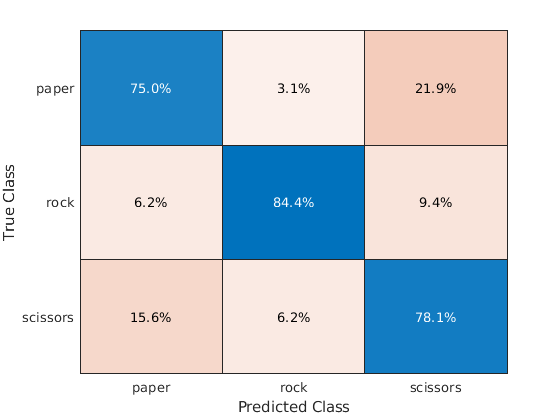

confusion_mat_norm1 =   ConfusionMatrixChart with properties:

    NormalizedValues: [3×3 double]
         ClassLabels: [3×1 categorical]

  Show all properties


confusion_mat_norm1 = confusionchart(train_labels, validationPredictions1, 'Normalization','row-normalized')

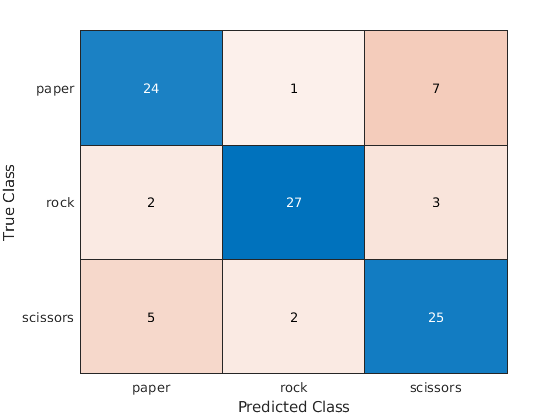

confusion_mat1 =   ConfusionMatrixChart with properties:

    NormalizedValues: [3×3 double]
         ClassLabels: [3×1 categorical]

  Show all properties


confusion_mat1 = confusionchart(train_labels, validationPredictions1)

# Export Model

Uncomment if want to re-export model

%save("data/trainedAlgorithm.mat", "trainedAlg");